clear;clc;close all
 % load('D:\OneDrive\文档\博士\学业\超快成丝\Filament_python\matlab保存数据\48637.mat')
 load("matlab保存数据\71706.mat")
% d2 = load('D:\OneDrive\文档\博士\学业\超快成丝\Filament_python\matlab保存数据\2.mat')
% x = d1.x;
% y = d1.y
% z_axis = d1.z_axis;

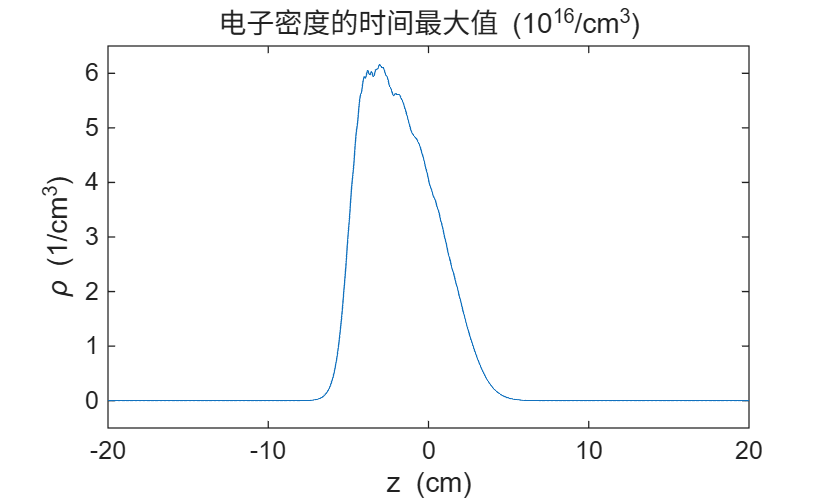

figure(5)
plot((z_axis-0.2)*1e2,rho_max_z/1e6/1e16);
xlim([-20,20]);ylim([-0.5,6.5])
xlabel('z  (cm)');ylabel('\rho (1/cm^3)');title('电子密度的时间最大值 (10^{16}/cm^3)')

figure(5)
plot((z_axis-0.2)*1e2,rho_onaxis_max_z/1e6/1e16);
xlim([-20,20]);ylim([-0.5,6.5])
xlabel('z  (cm)');ylabel('\rho (1/cm^3)');title('电子密度的时间最大值 (10^{16}/cm^3)')

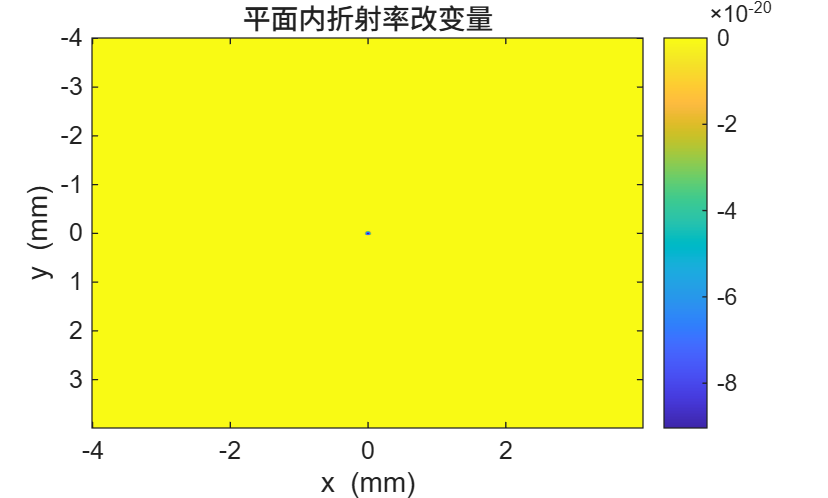

figure(1)
imagesc(x*1e3,y*1e3,dn_gas);
xlabel('x  (mm)');ylabel('y  (mm)');
colorbar;
title("平面内折射率改变量")

% figure(2)
% plot(z_axis,I_center_t0_z/1e4/1e12,'.');
% xlim([0.7,1.2])
% xlabel('z  (m)');ylabel('I  (TW/cm^2)');
% title("on-axis 像素处 t≈0 的强度")

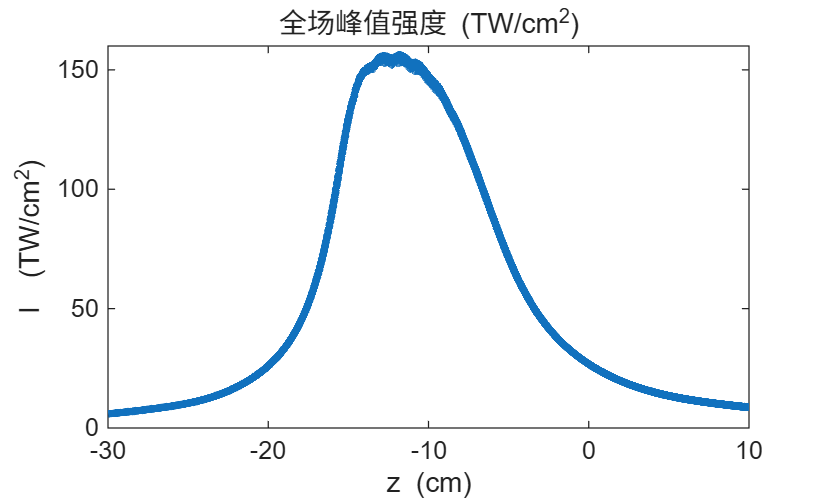

figure(3)
plot(1e2*(z_axis-0.3),I_max_z/1e4/1e12,LineWidth=3);
% xlim([0.7,1.2])
xlabel('z  (cm)');ylabel('I  (TW/cm^2)');
title("全场峰值强度 (TW/cm^2)")

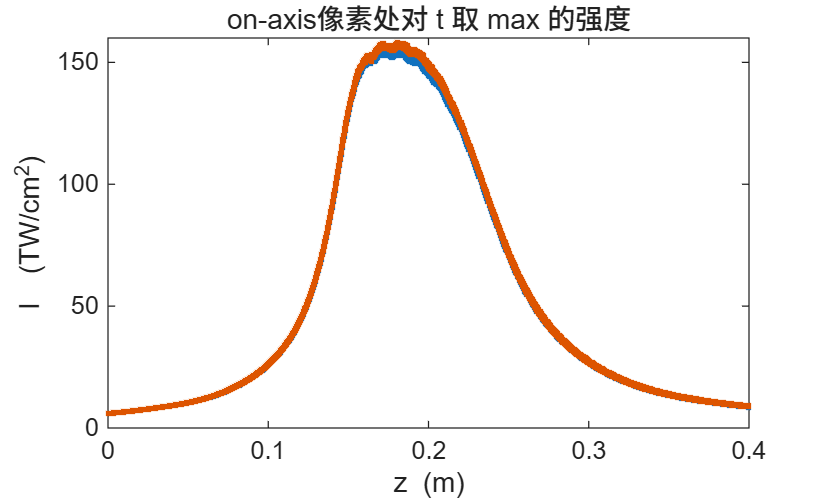

figure(8)
plot(z_axis,I_onaxis_max_z/1e4/1e12,'.');
hold on 
plot(z_axis,I_onaxis_max_interp_list/1e4/1e12,'.')
hold off
% xlim([0.7,1.2])
xlabel('z  (m)');ylabel('I  (TW/cm^2)');title('on-axis像素处对 t 取 max 的强度')

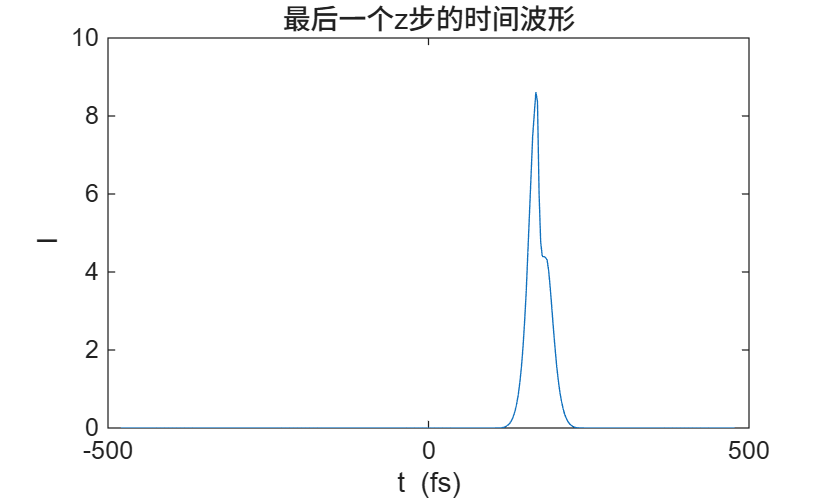

figure(4)
plot(t*1e15,I_out_center_t/1e4/1e12);
xlabel('t  (fs)');ylabel('I  ');
title("最后一个z步的时间波形")

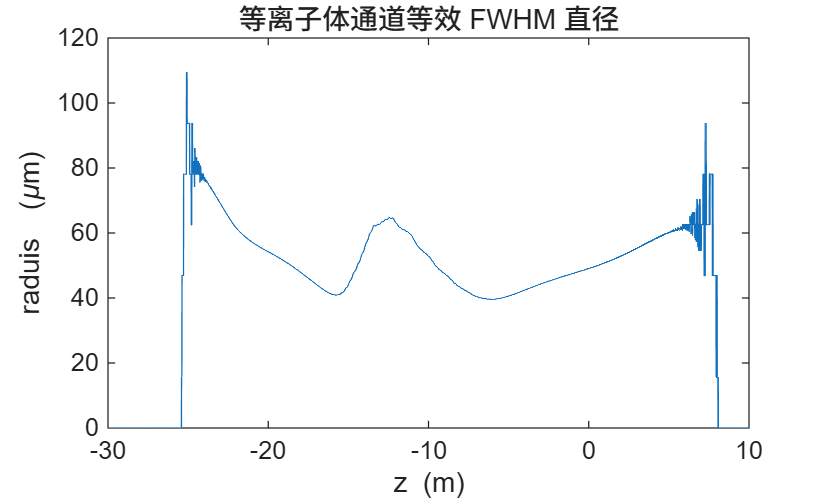

figure(11)
plot(1e2*(z_axis-0.3),fwhm_plasma_z*1e6)
% xlim([-12,13]);ylim([0,200])
xlabel('z  (m)');ylabel('raduis  (\mum)');title("等离子体通道等效 FWHM 直径")

% figure(6)
% plot((z_axis-0.3)*1e2,rho_onaxis_t_z(:,100)/1e6/1e16);
% xlim([-20,20])
% xlabel('z  (cm)');ylabel('\rho (1/cm^3)');title(' 电子密度的最大值 (10^{16}/cm^3)')

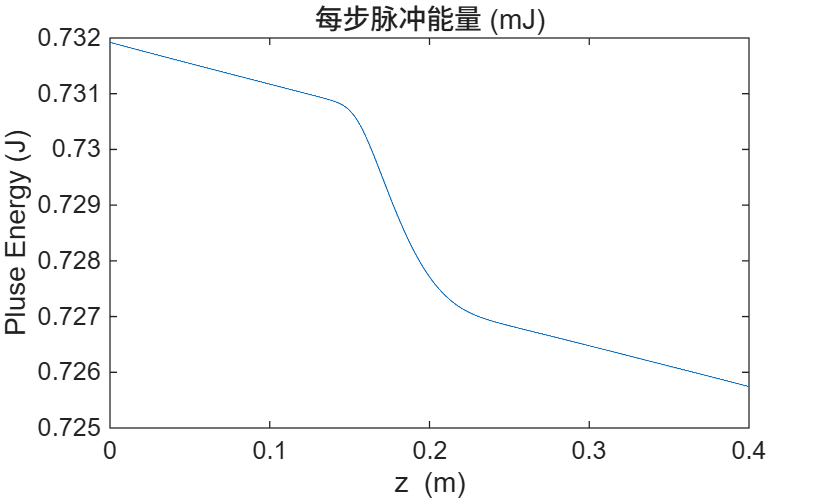

figure(7)
plot(z_axis,U_z*1e3);
% xlim([0.7,1.2])
xlabel('z  (m)');ylabel('Pluse Energy (J)');title('每步脉冲能量 (mJ)')

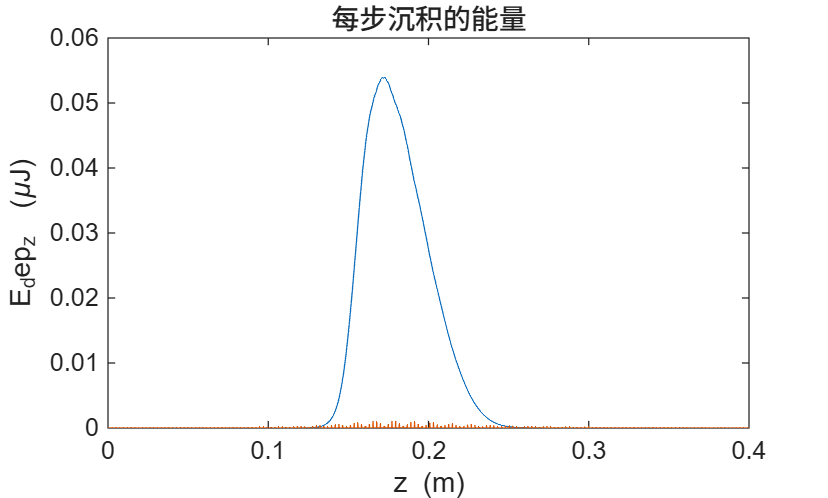

figure(9)
plot(z_axis,E_dep_z*1e6,z_axis,E_dep_rot_z*1e6);
xlabel('z  (m)');ylabel('E_dep_z  (\muJ)');title("每步沉积的能量")

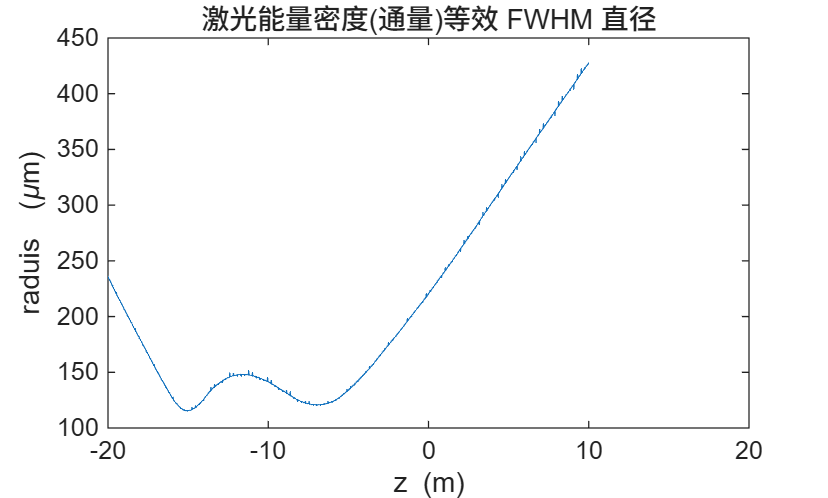

figure(10)
plot(1e2*(z_axis-0.3),fwhm_fluence_z*1e6)
xlim([-20,20]);%ylim([0,300])
xlabel('z  (m)');ylabel('raduis  (\mum)');title("激光能量密度(通量)等效 FWHM 直径")

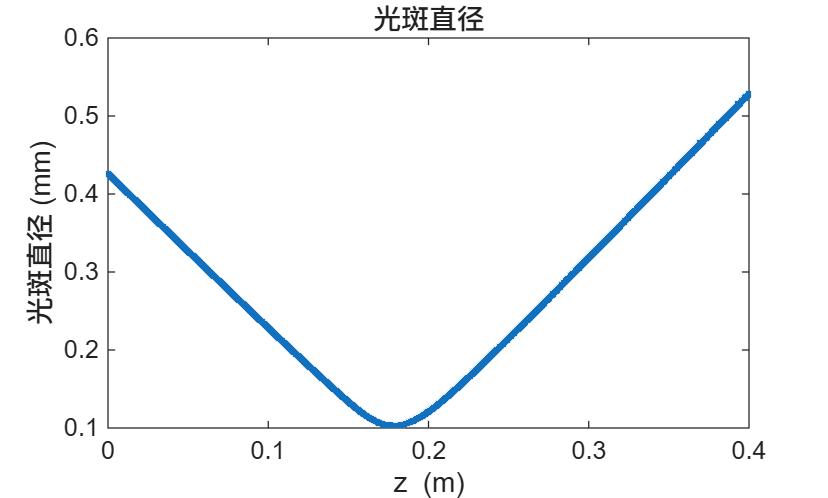

figure(14)
plot(z_axis,w_mom_z*1e3,'.')
xlabel('z  (m)');ylabel('光斑直径 (mm)');
title("光斑直径")